# Cinematica Inversa:

Este archivo contiene la cinematica inversa de un **Scara de 3DoF** y un **Antropomórfico ****sin codo**

## Antropomórfico (R3)

### Vista Isométrica

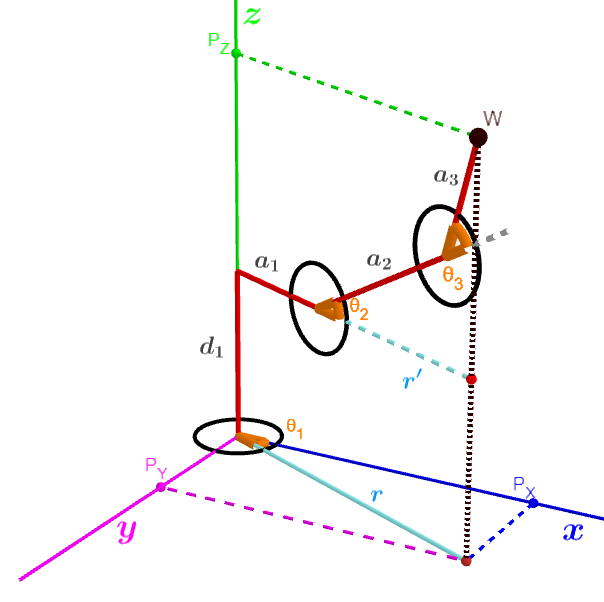

### Vista Superior

####  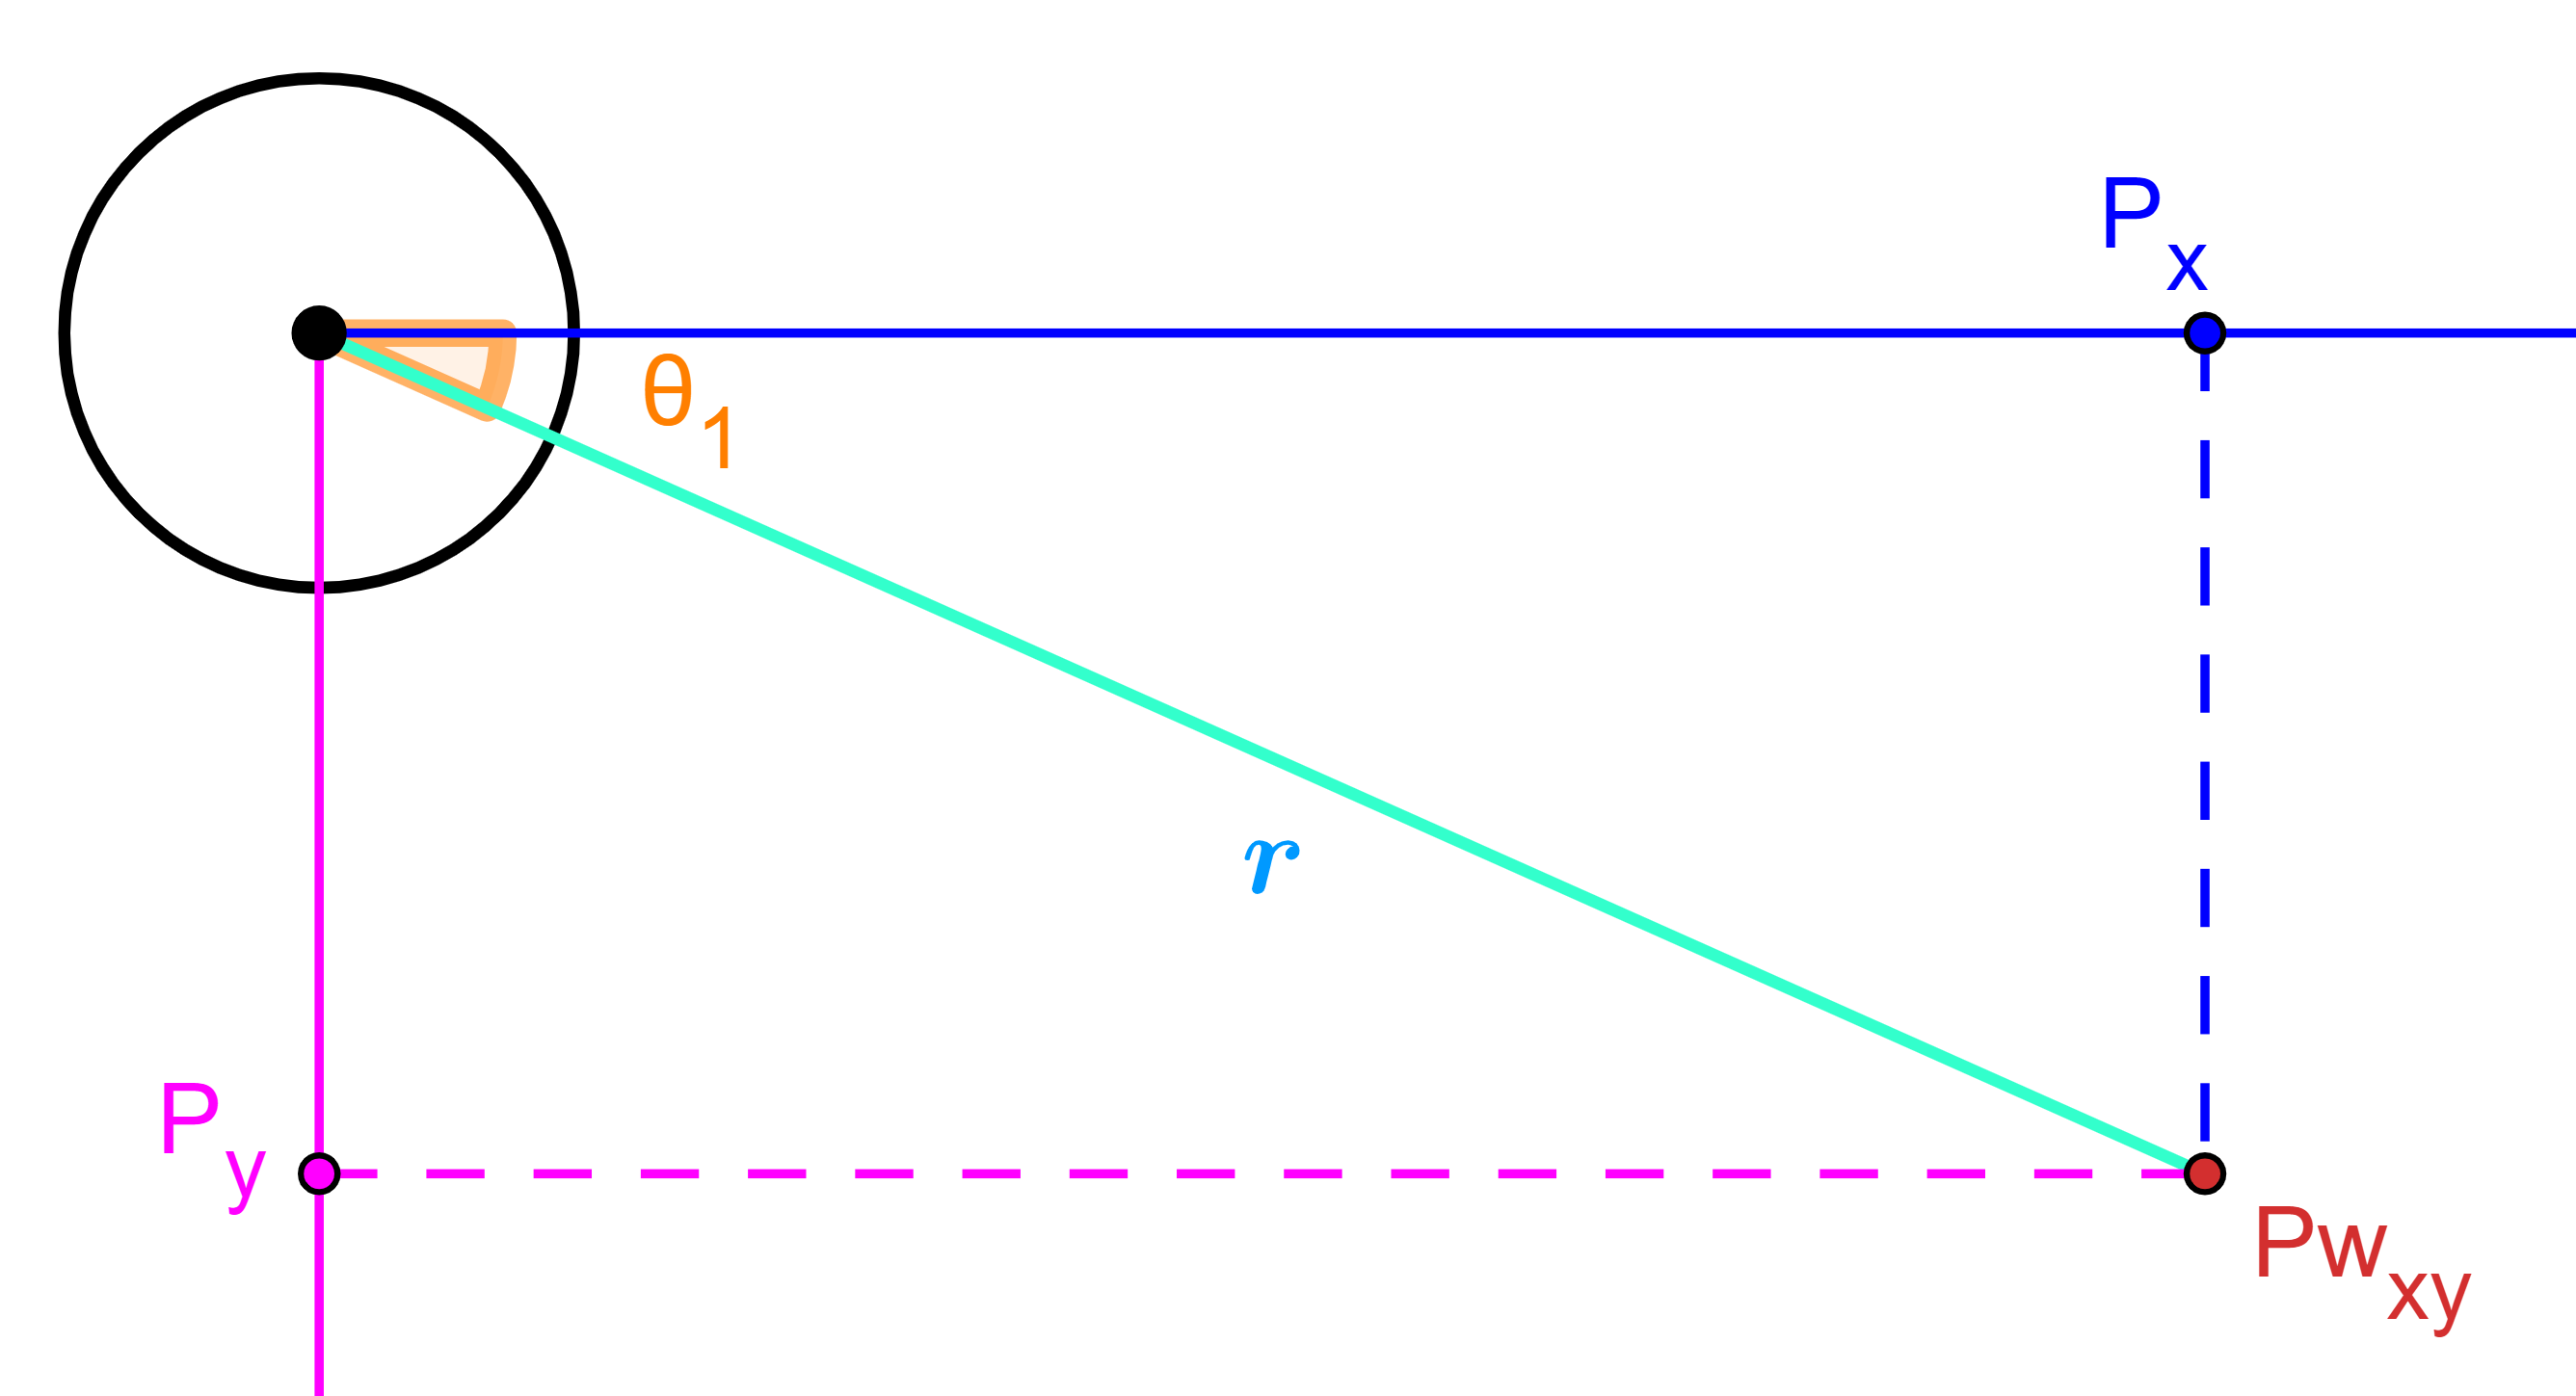

### Vista Lateral para θ2 y θ3

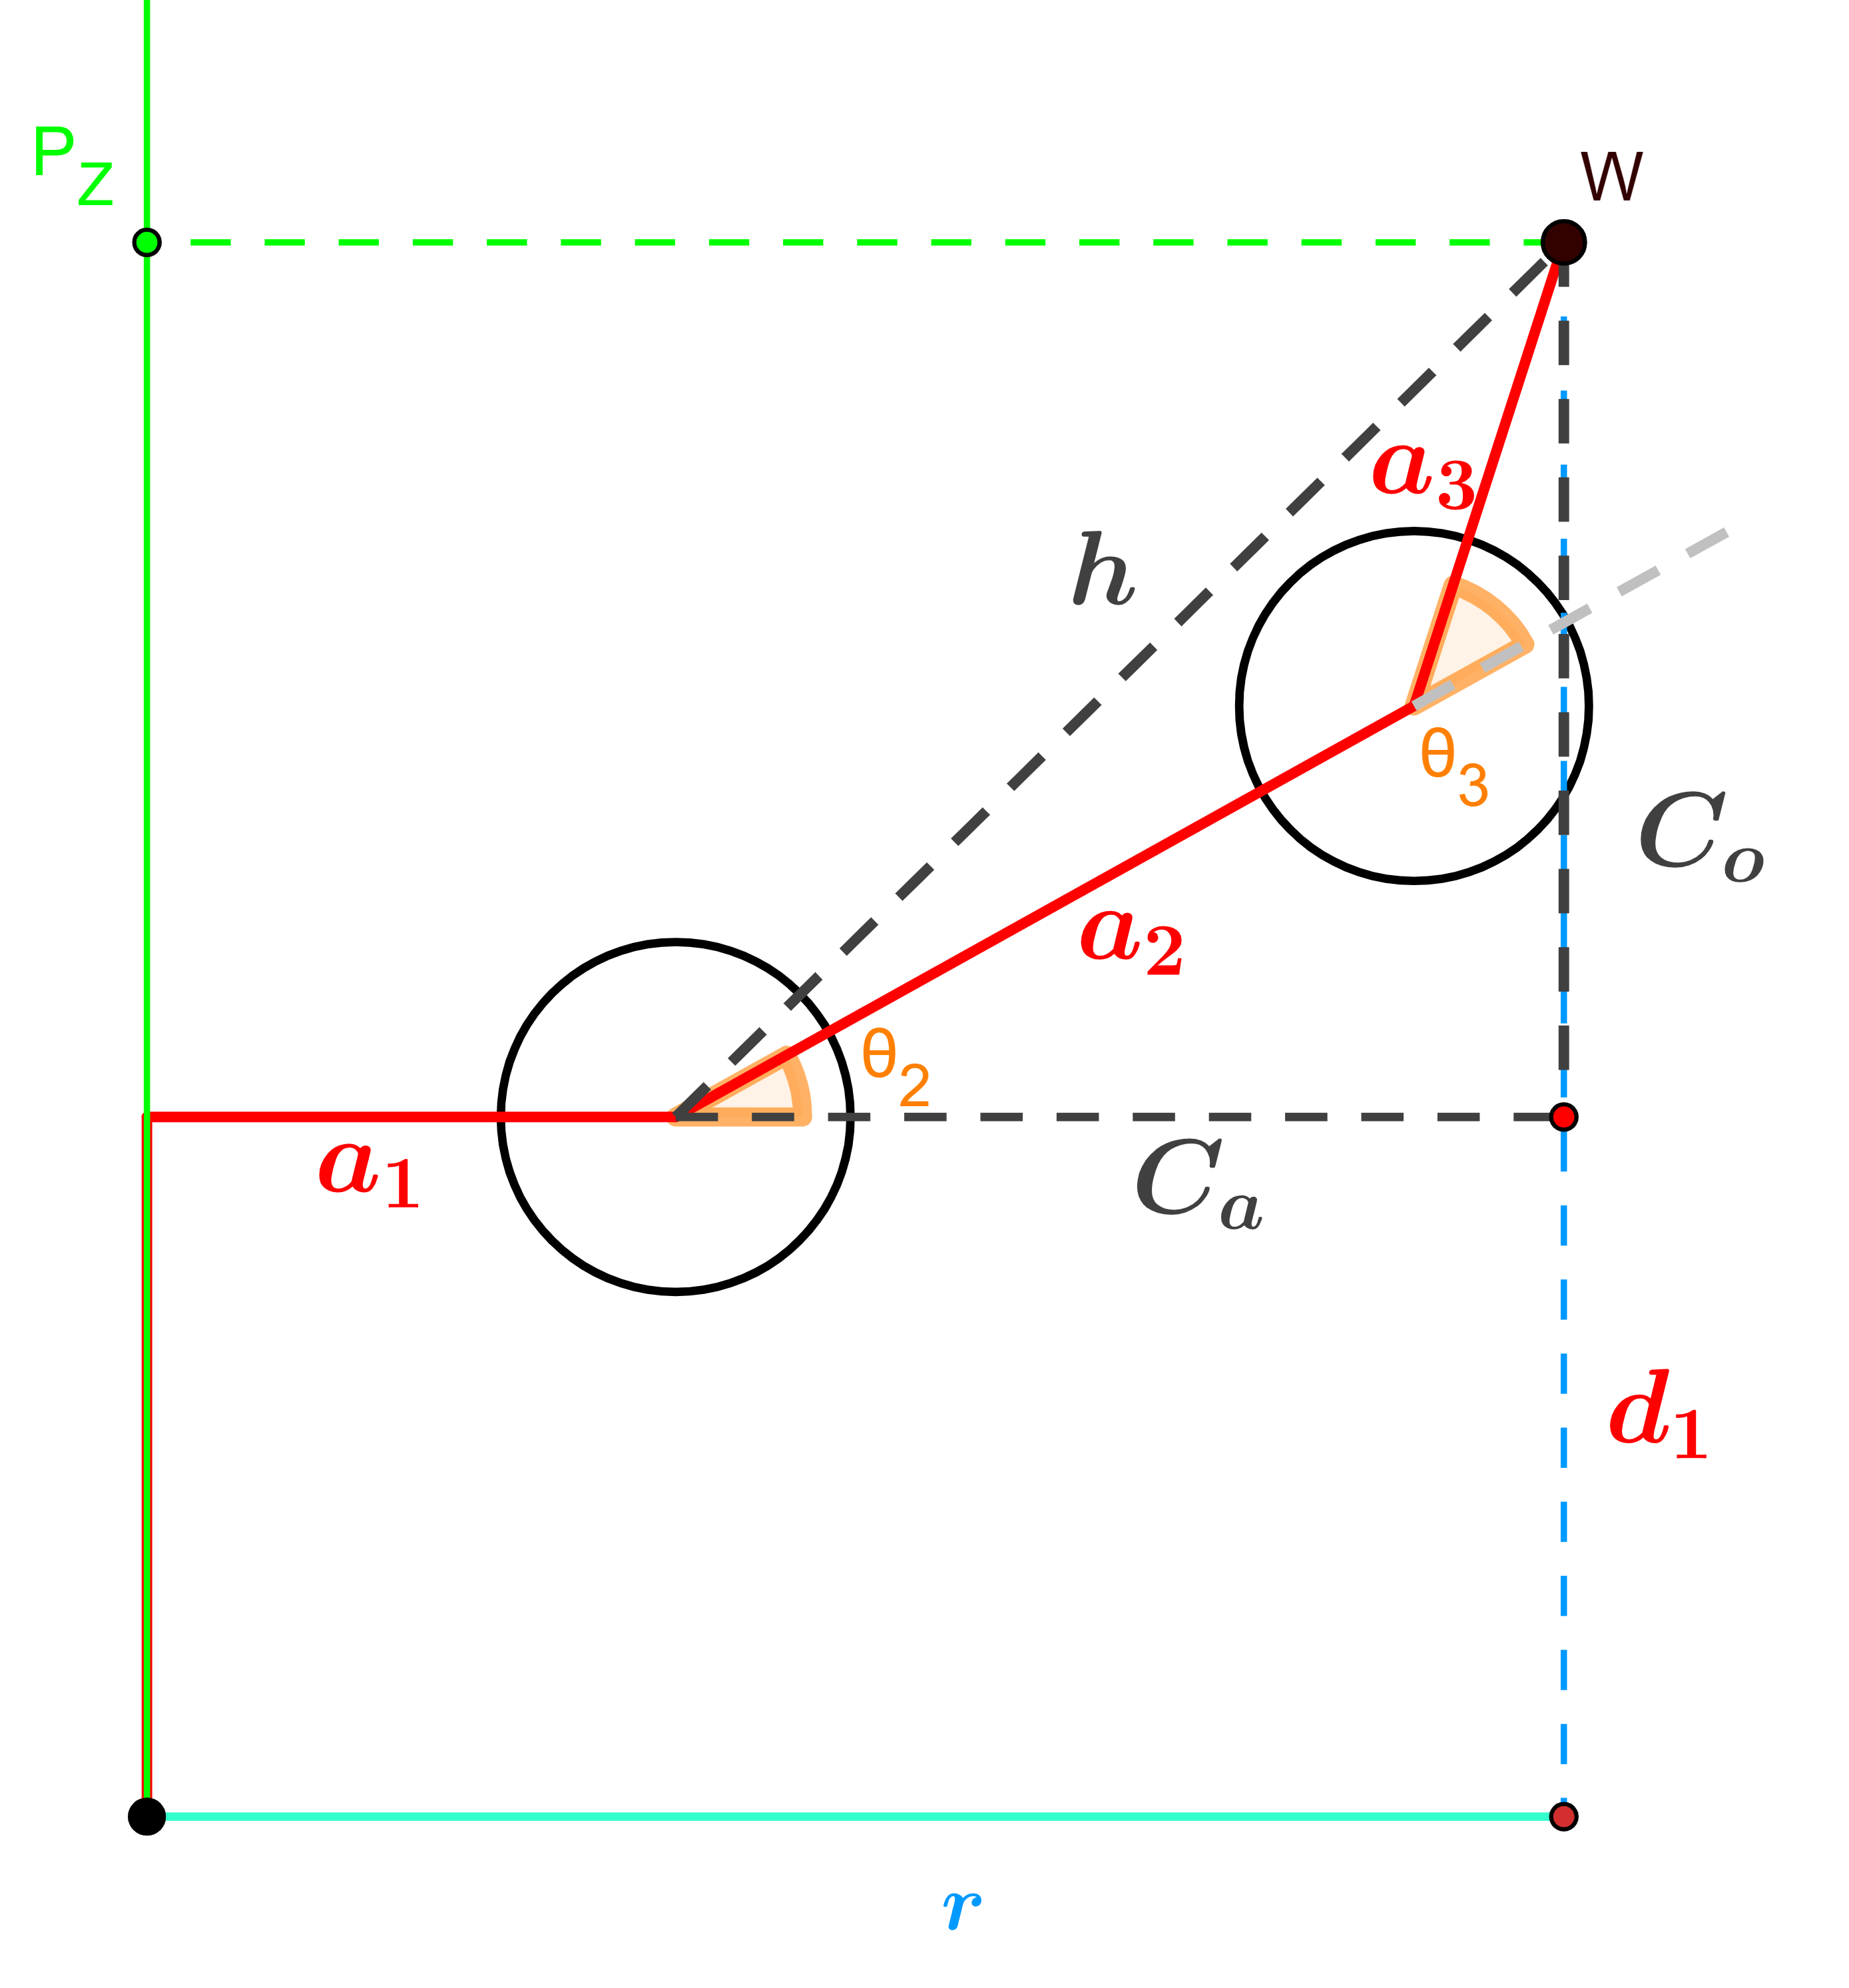

### Trinagulo Oblicuo Formado En Vista Lateral

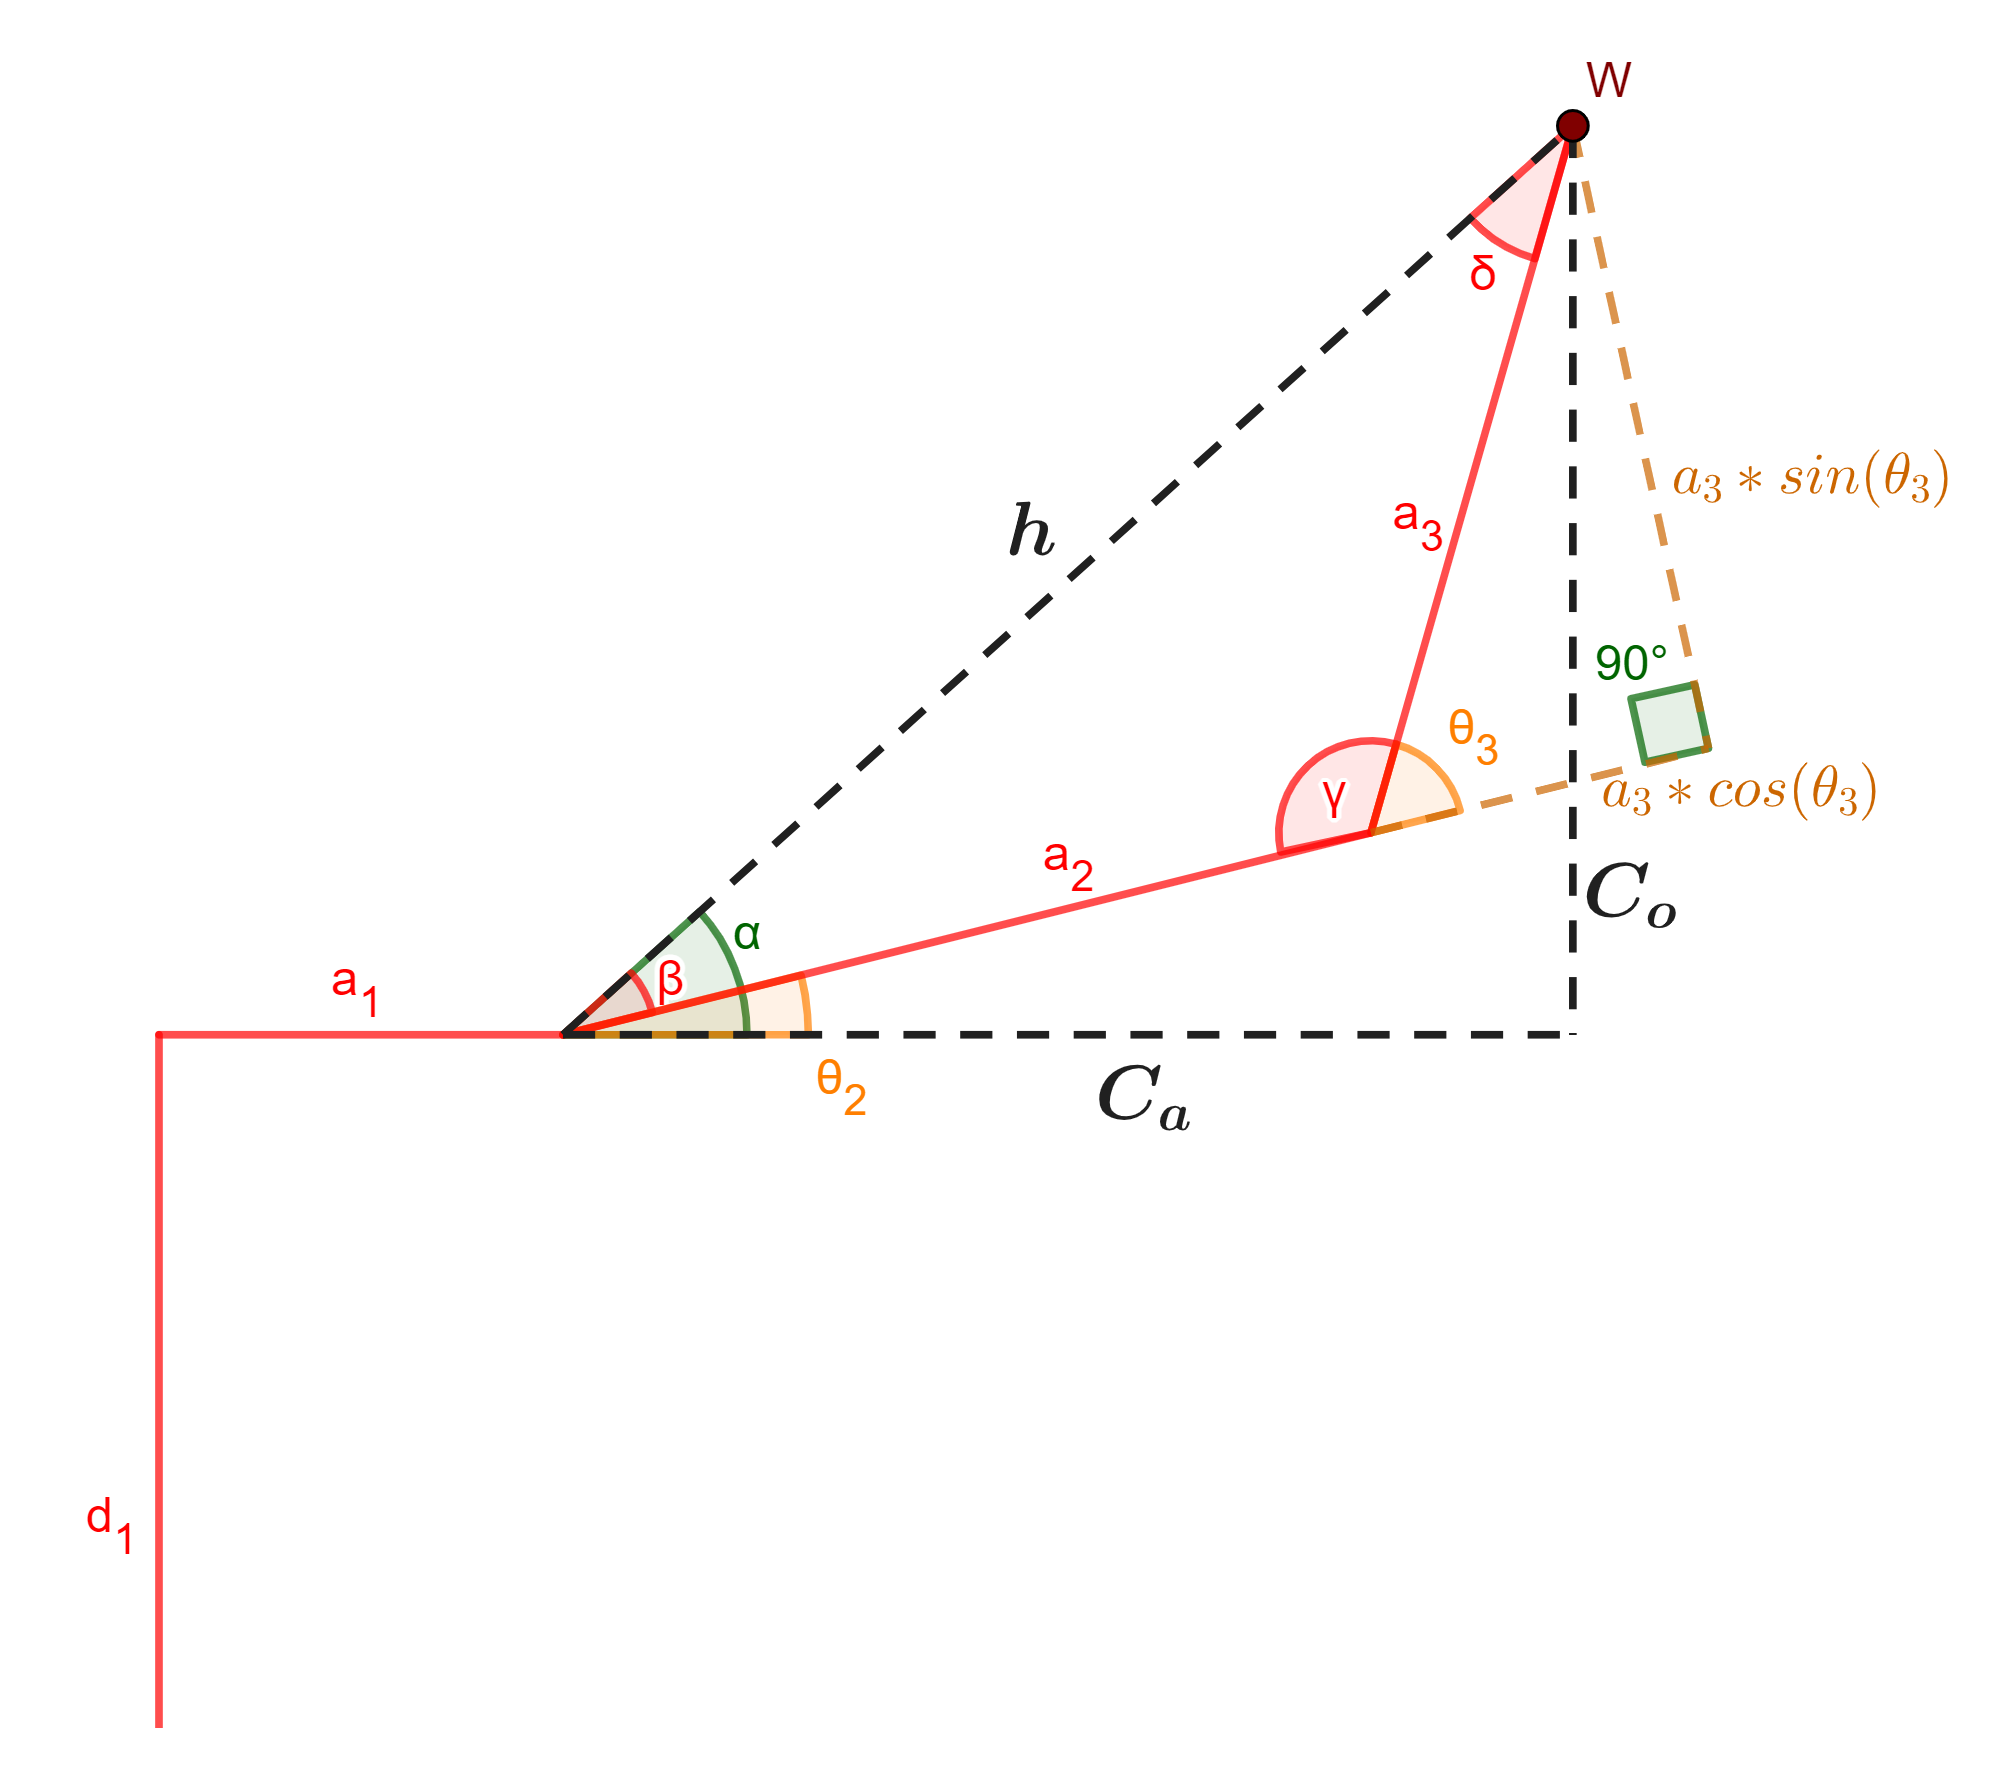

clear
syms P_X P_Y P_Z a_1 a_2 a_3 d_1 %Variables simbolicas para las ecuaciones de manera simbolica

#### Distacias entre eslabones

d_1=95.91;
a_2=66.76;
a_3=130.45;

#### Parametros ingresados (Posición y Orientacion)

P_X=-191.5;
P_Y=-38;
P_Z=98;
W=[P_X;P_Y;P_Z]

W =  -191.5000
  -38.0000
   98.0000


Calculo de **"h":** (***Hipotenusa**** del ****triangulo rectangulo**** formado en ****Z-r)=Base**** de ****triangulo Oblicuo****.*

r=sqrt(P_X^2+P_Y^2) %Hipotenusa del triangulo generado en el plano XY por proyección de Pw

r = 195.2338

Ca=r           %Cateto adyacente; Considerando la distancia a1 entre juntura 1-2

Ca = 195.2338

Co=P_Z-d_1          %Cateto opuesto; Considerando la distancia d1 entre juntura 1-2

Co = 2.0900

h=sqrt(Ca^2+Co^2)   %Base Del Triangulo Oblicuo

h = 195.2450

### Para θ1: Triangulo rectangulo formado en Plano XY

t1=atan2d(P_Y,P_X) %Calculo de Theta 1

t1 = -168.7764

### Para θ3: Teorema De Coseno

t3=-acosd((h^2-a_2^2-a_3^2)/(2*a_2*a_3)) %Calculo de Theta 3

t3 = -17.1132

***Codo arriba****=-acosd((h^2-a_2^2-a_3^2)/(2*a_2*a_3))*

***Codo abajo****=acosd((h^2-a_2^2-a_3^2)/(2*a_2*a_3))*

### Para  θ2=α-β 

#### Para "α": Por el triangulo rectangulo comprendido entre Ca-Co 

alpha=atan2d(Co,Ca) %Calculo de Alpha

alpha = 0.6133

#### Para "β": Teorema de Coseno

beta=acosd((a_3^2-a_2^2-h^2)/(-2*a_2*h)) %Calculo de Beta

beta = 11.3386

t2=alpha+beta %Calculo de Theta 2

t2 = 11.9519

***Codo arriba****=alpha+beta*

***Codo abajo****=alpha-beta*

### Comprobación

eslavones=3;
%Indica "1" Para las variables de Juntura%
matriz=[1, d_1, 90, 0;
        1, 0,   0, a_2;
        1, 0,   0, a_3];
A_T=DH(eslavones,matriz,[t1,t2,t3])

A_T =    -0.9769   -0.0882   -0.1946 -191.5000
   -0.1938   -0.0175    0.9809  -38.0000
   -0.0900    0.9959         0   98.0000
         0         0         0    1.0000


if (round(A_T(1:3,4),5)==W)
    disp("Funciona")
else
    disp("Solución no viable")
end

Funciona


## Scara P2R

### Vista Isometrica

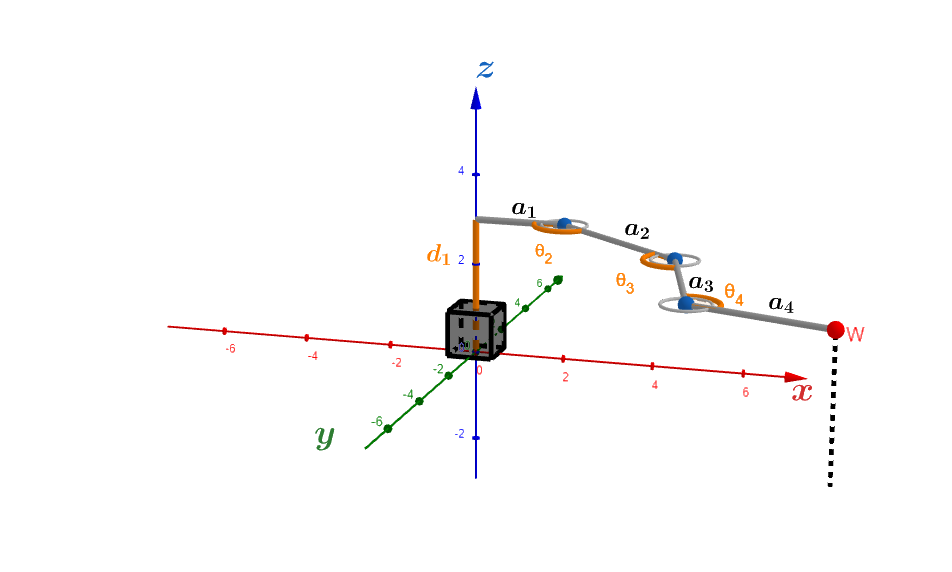

### Vista Superior

*Se forma el ****Triangulo Oblicuo**** para aplicar ****teorema de Cos**** y resolver por ****metodos geometricos***

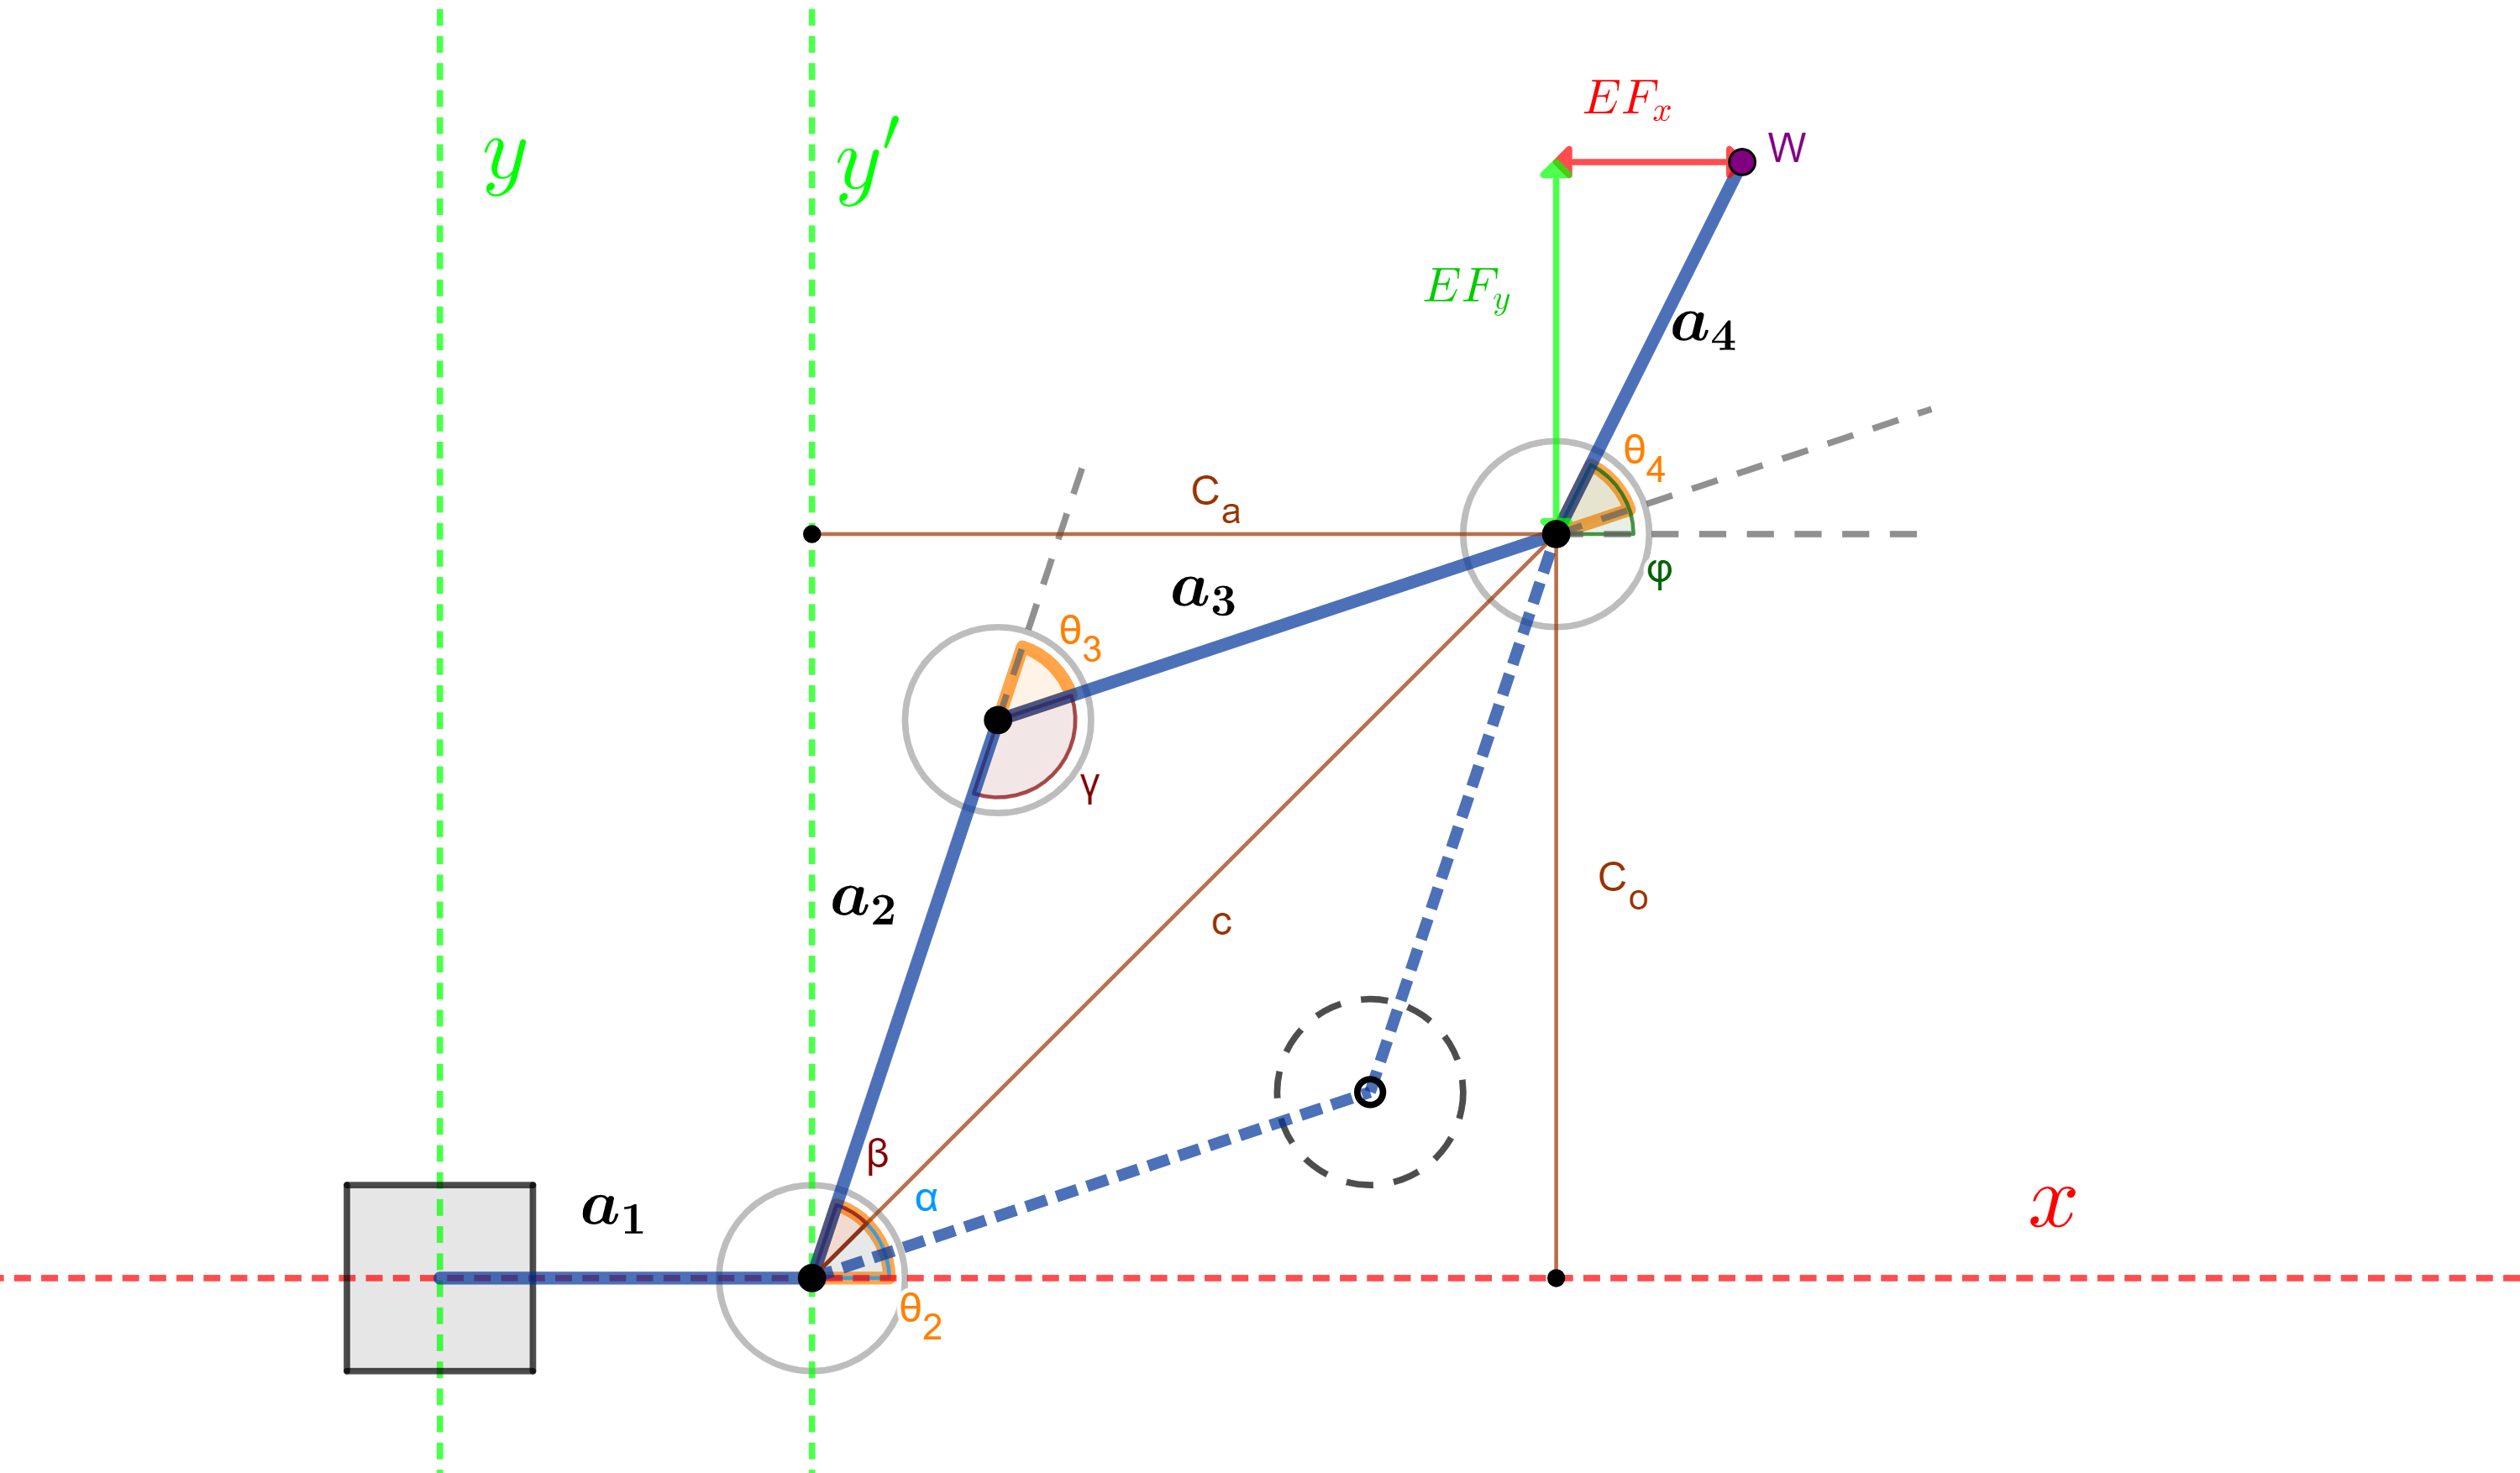

clear
syms P_X P_Y P_Z phi a_1 a_2 a_3  %Variables simbolicas para las ecuaciones de manera simbolica

#### Distacias entre eslabones

a_1=47.3;
a_2=149.1;
a_3=148.8;

#### Parametros ingresados (Posición y Orientacion)

P_X=0; %Punto en X
P_Y= 0; %Punto en Y
P_Z=  0; %Punto en Z
W=[P_X;P_Y;P_Z] %Vector de Posición

W =      0
     0
     0


Calculo de **"c":** ***Hipotenusa**** del ****triangulo rectangulo**** formado en ****X-Y';*** ***Base**** de ****triangulo Oblicuo****.*

Ca=P_X-a_1;    %Cateto Adyacente del triangulo formado en X-Y'
Co=P_Y;        %Cateto Opuesto del triangulo formado en X-Y'
c=sqrt(Ca^2+Co^2); %Hipotenusa del triangulo rectangulo formado en X-Y'; Base de triangulo Oblicuo.

### Para θ3: Teorema De Coseno

t3=acosd((c^2-a_2^2-a_3^2)/(2*a_2*a_3)) %Calculo de Theta3

t3 = 161.7284

***Codo arriba****=-acosd((c^2-a_2^2-a_3^2)/(2*a_2*a_3))*

***Codo abajo****=acosd((c^2-a_2^2-a_3^2)/(2*a_2*a_3))*

### Para  θ2=α-β 

*Para ****"α"**** por el**** triangulo rectangulo**** comprendido entre ****X-Y' (Ca-Co)***

alpha=atan2d(Co,Ca); %Calculo de alpha

*Para ****"β"**** por el ****teorema del coseno***

beta=acosd((a_2^2+c^2-a_3^2)/(2*a_2*c)); %Calculo de beta
t2=alpha-beta %Calculo de Theta2

t2 = 99.4946

***Codo arriba****=alpha+beta*

***Codo abajo****=alpha-beta*

### Para  d1 (Distancia en el eje Z)=Pz

d1=P_Z %Calculo de d1 (Desplazamiento de la base)

d1 = 0

### Comprobación

eslavones=3;
%Indica "1" Para Las Variables De Juntura%
matriz=[0, 1, 0, a_1;
          1, 0, 0, a_2;
          1, 0, 0, a_3;
];
A_T=DH(eslavones,matriz,[d1,t2,t3])

A_T =    -0.1526    0.9883         0   -0.0000
   -0.9883   -0.1526         0    0.0000
         0         0    1.0000         0
         0         0         0    1.0000


if (round(A_T(1:3,4),5)==W)
    disp("Funciona")
else
    disp("Solución no viable")
end

Funciona


function Matriz_DH=DH(n,matriz,junturas)%Funcion Para Matriz DH (Final)
    Matriz_T=eye(4);
    for i=1:n
        angz=matriz(i,1);
        d=matriz(i,2);
        angx=matriz(i,3);
        a=matriz(i,4);
        for j=1:2
            if matriz(i,1)==1
               angz=junturas(i); 
            else
                d=junturas(i); 
            end
        end                
        Ma_S=parametros(0,1,angz,d,angx,a);
        Matriz_T=Matriz_T*Ma_S; %Matrices DH PostMultiplicacion (A01*A12,A01*A12*A23...)
    end
    Matriz_DH=Matriz_T;  %Matriz DH (A01*....A(n-1,n))
end
function Homogenea=parametros(tipo,cual,angz,d,angx,a)%Calculo de la Matriz homogenea de DH (por eslabon)
%Para Matriz Completamente simbolica enviar (1,n,1,1,1,1)
%Para Matriz con Variables de Juntura Rotacionales Simbolicas enviar (2,n,1,d,angx,a)
%Para Matriz Evaluada o con Variables de Juntura Prismaticas Simbolicas enviar (0,n,angz,(1/d),angx,a)
    Tabla_D=SB(cual);
    vec=[angz,d,angx,a];   
    if tipo==0      
        if (vec(2)==1)
            fila=Tabla_D(cual,2);
        else
            fila=vec(2);    
        end        
        Homogenea=[cosd(angz), -sind(angz)*cosd(angx),  sind(angz)*sind(angx), a*cosd(angz);
                   sind(angz),  cosd(angz)*cosd(angx), -cosd(angz)*sind(angx), a*sind(angz);
                            0,             sind(angx),             cosd(angx),         fila;
                            0,                      0,                      0,            1];
    elseif tipo==1  
        for j=1:cual
            for k=1:4
                if (vec(k)==1)
                   fila(k)=Tabla_D(j,k);
                else
                    fila(k)=vec(k);
                end
            end
        end     
        
        %Calculo de la Matriz Simbolica homogenea de DH (por eslabon)
        Homogenea=[cos(fila(1)), -sin(fila(1))*cos(fila(3)),  sin(fila(1))*sin(fila(3)), fila(4)*cos(fila(1));
                   sin(fila(1)),  cos(fila(1))*cos(fila(3)), -cos(fila(1))*sin(fila(3)), fila(4)*sin(fila(1));
                    0,                  sin(fila(3)),            cos(fila(3)),           fila(2);
                    0,                          0,                    0,           1];
    else
        if (vec(1)==1)
            fila=Tabla_D(cual,1);
        else
            fila=vec(1);    
        end 
        %Calculo de la Matriz Simbolica Con Theta homogenea de DH (por eslabon)
        Homogenea=[cos(fila(1)), -sin(fila(1))*cosd(angx),  sin(fila)*sind(angx), a*cos(fila);
                   sin(fila(1)),  cos(fila(1))*cosd(angx), -cos(fila)*sind(angx), a*sin(fila);
                           0,                  sind(angx),               cosd(angx),              d;
                           0,                     0,                     0,           1];
    end
end
function simbolos=SB(n)
    T=[sym('theta_%d',[1 n+1])];
    d=[sym('d_%d',    [1 n+1])];
    A=[sym('alpha_%d',[1 n+1])];
    a=[sym('a_%d',    [1 n+1])];
    simbolos=[transpose(T) transpose(d) transpose(A) transpose(a)];
end
function Tabla_DH=T_DH(i,matrix) %Funcion para Tabla de Parametros DH
    syms theta_n d_n alpha_n a_n
    Tabla_D=SB(i-1);
    for j=1:i
        for k=1:4
            if (matrix(j,k)~=1 && matrix(j,k)~=0)
                Tabla_D(j,k)=1;
            end
        end        
        Tabla_T(j,:)=Tabla_D(j,:).*matrix(j,:);
    end
    Tabla_DH=[theta_n d_n alpha_n a_n;Tabla_T];
end